# Create Deep Learning Network Architecture

Script for creating the layers for a deep learning network with the following properties:

Run the script to create the layers in the workspace variable `layers`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 12-Nov-2021 18:20:42

## Create Array of Layers

layers = [
    imageInputLayer([227 227 3],"Name","imageinput")
    convolution2dLayer([11 11],96,"Name","conv1","BiasLearnRateFactor",2,"Stride",[4 4])
    reluLayer("Name","relu1")
    crossChannelNormalizationLayer(5,"Name","normalization1","K",1)
    maxPooling2dLayer([3 3],"Name","maxpool1","Stride",[2 2])
    convolution2dLayer([5 5],32,"Name","conv2","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","relu2")
    crossChannelNormalizationLayer(5,"Name","normalization2","K",1)
    maxPooling2dLayer([5 5],"Name","maxpool2","Padding","same")
    convolution2dLayer([3 3],32,"Name","conv3","BiasLearnRateFactor",2,"Padding","same")
    reluLayer("Name","relu3")
    convolution2dLayer([3 3],32,"Name","conv4","BiasLearnRateFactor",2,"Padding","same")
    reluLayer("Name","relu4")
    convolution2dLayer([3 3],32,"Name","conv5","BiasLearnRateFactor",2,"Padding","same")
    reluLayer("Name","relu5")
    maxPooling2dLayer([5 5],"Name","maxpool5","Padding","same")
    fullyConnectedLayer(4096,"Name","fc6","BiasLearnRateFactor",2)
    reluLayer("Name","relu6")
    dropoutLayer(0.5,"Name","dropout6")
    fullyConnectedLayer(4096,"Name","fc7")
    reluLayer("Name","relu7")
    dropoutLayer(0.5,"Name","dropout7")
    fullyConnectedLayer(1000,"Name","fc8","BiasLearnRateFactor",2)];

## Plot Layers

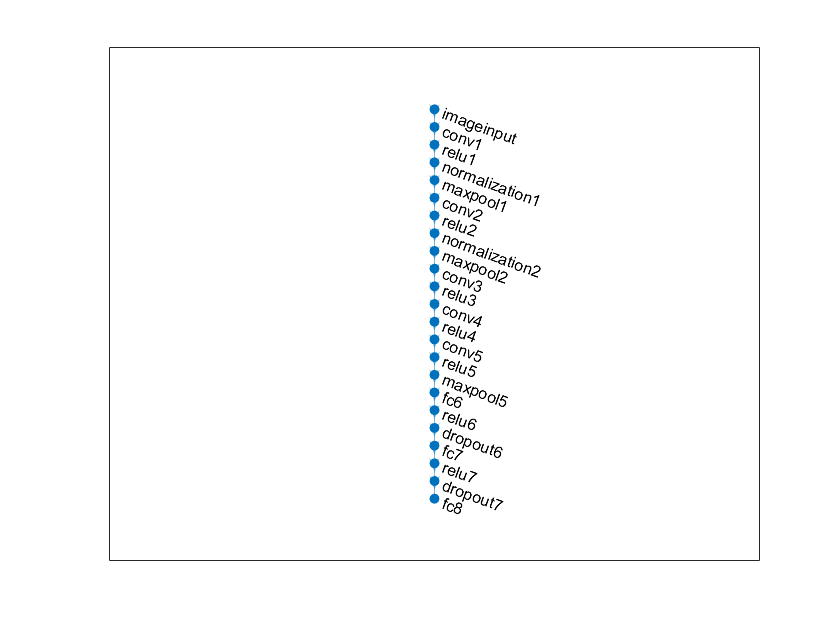

plot(layerGraph(layers));